FA =     1.0000    0.5000         0   -0.0056
         0    0.9997         0   -0.0225
         0    0.0056    1.0000    0.5000
         0    0.0225         0    0.9997


QA =    -0.4166   -2.4998   -0.0133   -0.0859
    2.2917    8.7480    0.0927    0.4002
   -0.0075   -0.0391   -0.1042   -0.6248
   -0.0186   -0.1211    0.5708    2.1774


FB =     1.0000    0.5000         0    0.0056
         0    0.9997         0    0.0225
         0   -0.0056    1.0000    0.5000
         0   -0.0225         0    0.9997


QB =    -0.4166   -2.4998   -0.0075   -0.0391
    2.2890    8.7375    0.0218    0.0371
   -0.0133   -0.0859   -0.1042   -0.6248
    0.1331    0.5584    0.5734    2.1879


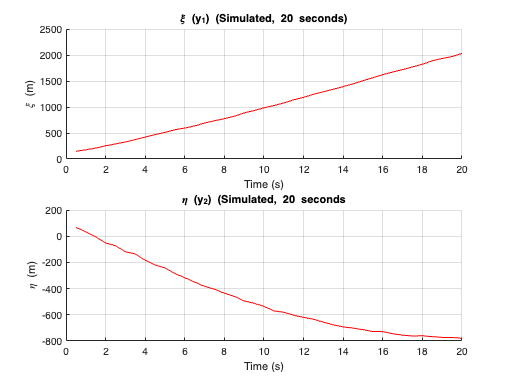

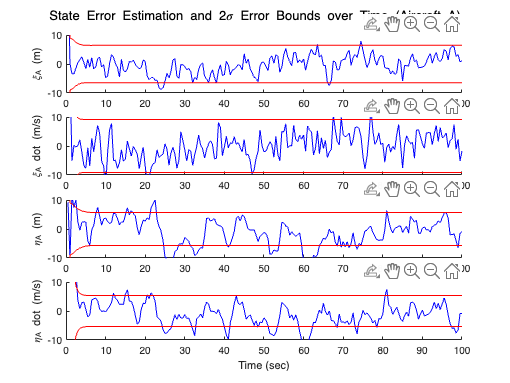

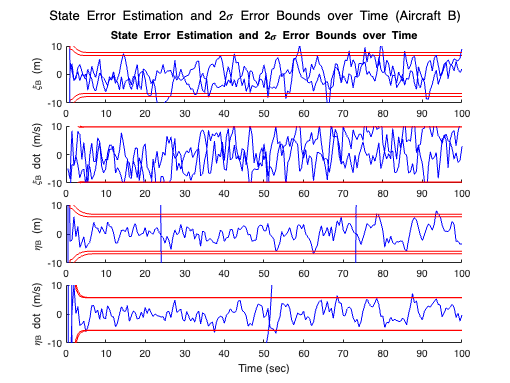

Fd =          0         0         0   -0.0112
         0         0         0   -0.0450
         0    0.0112         0         0
         0    0.0450         0         0


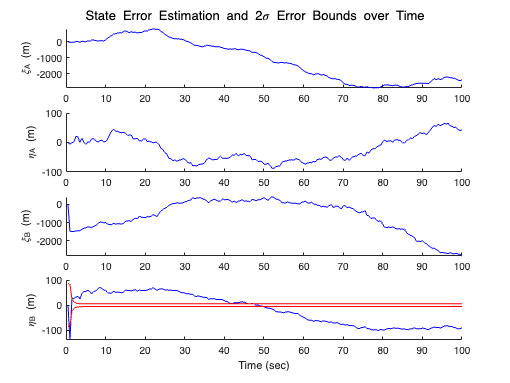

% ASEN 5044
% HWK 7
clear

rng(100);
close all;
%%%%%%%%%%
% Q1
%%%%%%%%%%

oma = 0.045;
omega = oma;
omb = -0.045;
dt = 0.5;
qw = 10;
W = qw * [2 0.05; 0.05 0.5];
Aa = [0 1 0 0 ; 0 0 0 -oma; 0 0 0 1; 0 oma 0 0 ];
Ab = [0 1 0 0 ; 0 0 0 -omb; 0 0 0 1; 0 omb 0 0 ];

lambda = [0 0;1 0; 0 0 ; 0 1];

za = dt *[-Aa, lambda * W * lambda'; zeros(4,4), Aa'];
Za = expm(za);
FA = Za(5:8,5:8)';
QA = FA' * Za(1:4,5:8);

zb = dt *[-Ab, lambda * W * lambda'; zeros(4,4), Ab'];
Zb = expm(zb);
FB = Zb(5:8,5:8)';
QB = FB' * Zb(1:4,5:8);
%%%%%%%%%%%%%
% Q2 Part a %
%%%%%%%%%%%%%
n = 200;
HA = [ 1 0 0 0; 0 0 1 0];
RA = [20 0.05; 0.05 20];
q8data = importdata("hw8problemdata.mat");
GTsingleA = q8data.xasingle_truth;
xa0 = GTsingleA(1:4,1:1);

% get matrix sqrt of R
Sv = chol(RA,'lower');
Qk = randn(2,n);      % generate 200 random distribution
% generate simulated measurements for y1, y2
for i = 1:n
    y(:,i) = HA * GTsingleA(:,i+1) + Sv * Qk(:,i);
end

figure(1)
% Plot the results.
set(gcf,'Color','white');
N = 40;
k = 1 : N;
subplot(2,1,1); hold on;
plot(k/2, y(1,1:N), 'r-');
set(gca,'FontSize',10); grid on; 
title('\xi (y_1) (Simulated, 20 seconds)');
ylabel('\xi (m)'); xlabel('Time (s)')

subplot(2,1,2); hold on;
plot(k/2, y(2,1:N), 'r-');
set(gca,'FontSize',10); grid on; 
title('\eta (y_2) (Simulated, 20 seconds');
ylabel('\eta (m)'); xlabel('Time (s)')

% Q2 Part b %
n = 200;
PArr = []; xhatArr = []; 
M = [0; 85*cos(pi/4); 0; -85*sin(pi/4)];
P0 = 900 * diag([10 2 10 2]);
sigma = 2 * sqrt(diag(P0));
xhatArr(:,:,1) = M;
xhat_p = FA * M;
PA_p = P0;
PArr(:,:,1) = [PA_p];
xerror = xa0 - xhat_p;
for k = 2:n
    % time update
    xhat_m = FA * xhat_p ;
    PA_m = FA * PA_p * FA' + QA ; 
    KA = PA_m * HA' * inv(HA * PA_m * HA' + RA);
    % msmt update
    xhat_p = xhat_m + KA * (y(:,k) - HA * xhat_m);
    PA_p = (eye(4) - KA * HA) * PA_m; 
    % p_plus and x_plus become p_minus and x_minus
    PA_m = PA_p; xhat_m = xhat_p;
    xhatArr = [xhatArr xhat_p];
    PArr(:,:,k) = [PA_p];
    sigma(:,k) = 2 * sqrt(diag(PA_p));
    xerror(:,k) = GTsingleA(:,k+1) - xhat_p;
end

% Plot the results.
figure(2); % open a new figure
set(gcf,'Color','white');
k = 1 : 200;
subplot(4,1,1); hold on;
plot(k/2, xerror(1,1:200), 'b');
 plot(k/2, sigma(1,:) , 'r' )
 plot(k/2, -sigma(1,:) , 'r' )
set(gca,'FontSize',10);
sgtitle('(#2) State Error Estimation and 2\sigma Error Bounds over Time (Aircraft A)');
ylabel('\xi_A (m)');ylim([-10 10]);

subplot(4,1,2); hold on;
plot(k/2, xerror(2,1:200), 'b');
plot(k/2, sigma(2,:) , 'r' )
plot(k/2, -sigma(2,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\xi_A dot (m/s)');ylim([-10 10]);

subplot(4,1,3); hold on;
plot(k/2, xerror(3,1:200), 'b');
plot(k/2, sigma(3,:) , 'r' )
plot(k/2, -sigma(3,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\eta_A (m)'); ylim([-10 10]);

subplot(4,1,4); hold on;
plot(k/2, xerror(4,1:200), 'b');
plot(k/2, sigma(4,:) , 'r' )
plot(k/2, -sigma(4,:) , 'r' )
set(gca,'FontSize',10); ylim([-10 10]);
ylabel('\eta_A dot (m/s)'); xlabel('Time (sec)')
hold off

%%%%%%%%%%%%%%
% Q 3 Part a %
%%%%%%%%%%%%%%
n = 200;

Ma = [0; 85*cos(pi/4); 0; -85*sin(pi/4)];
Pa0 = 900 * diag([10 2 10 2]);
Mb = [3200; 85*cos(pi/4); 3200; -85*sin(pi/4)];
Pb0 = 900 * diag([11 4 11 4]);

% sensor variance for y_D
RD = [10 0.15; 0.15 10];
% H matrix for msmts rA and rB where Ya = rA & Yd = rA - rB
HD = [1 0 0 0 -1 0 0 0; 0 0 1 0 0 0 -1 0]; % y1a - y1b; y5a - y5b
Hd = [1 0 0 0; 0 0 1 0]; % [y1a-y1b; y3a - y3b]
HS = [1 0 0 0 0 0 0 0;  
      0 0 1 0 0 0 0 0; 
      1 0 0 0 -1 0 0 0; 
      0 0 1 0 0 0 -1 0];  
% build other system matrices
FS = blkdiag(FA,FB);
QS = blkdiag(QA,QB);
Ps0 = blkdiag(Pa0,Pb0);
RS = [blkdiag(RA,RD)];

Ms = [Ma;Mb];   % OR THIS SHOULD BE (Ma,Ma-Mb)????
%Md = [Ma;Ma-Mb];   % OR THIS SHOULD BE (Ma,Ma-Mb)????
sigmaS = 2 * sqrt(diag(Ps0));

% import data
GTa = q8data.xadouble_truth;
GTb = q8data.xbdouble_truth;

% first item is initial X
Xa0 = GTa(1:4,1:1);
Xb0 = GTb(1:4,1:1);
%Xd0 = [Xa0;Xa0 - Xb0];
Xs0 = [Xa0 ; Xb0];
Xs = [GTa;GTb];
% get matrix sqrt of RD
SvD = chol(RD,'lower');
Qd = randn(4,n);      % generate 200 samples for yd1,yd2
% generate simulated measurements for y1, y2, y3, y4
for i = 1:n
  ya(:,i) = HA * GTa(:,i+1) + Sv * Qd(1:2,i); % generate simulated Ya data
  yd(:,i) = Hd * (GTa(:,i+1) - GTb(:,i+1)) + SvD * Qd(3:4,i); % generate simulated Ya-Yb data
end
% stack msmt vectors
Ys= [ya;yd];

PArrD = []; xhatArrD = [];
xhatS_p = FS * Ms;
%xhatArrD(:,:,1) = xhatD_p;
Ps_p = Ps0;
PArrS(:,:,1) = Ps_p;
xserror = Xs0 - xhatS_p;
for k = 2:n
    % time update
    xhatS_m = FS * xhatS_p ;
    Ps_m = FS * Ps_p * FS' + QS ; 
    KS = Ps_m * HS' * inv(HS * Ps_m * HS' + RS);
    % msmt update
    xhatS_p = xhatS_m + KS * (Ys(:,k) - HS * xhatS_m);
    Ps_p = (eye(8) - KS * HS) * Ps_m; 
    Ps_m = Ps_p; xhatS_m = xhatS_p;
    PArrS(:,:,k) = Ps_p;
    sigmaS(:,k) = 2 * sqrt(diag(Ps_p));
    xserror(:,k) = [GTa(:,k+1); GTb(:,k+1)] - xhatS_p;
end

% Plot the results.
figure(3); % open a new figure for Aircraft A
set(gcf,'Color','white');
k = 1 : 200;
subplot(4,1,1); hold on;
plot(k/2, xserror(1,1:200), 'b');
 plot(k/2, sigmaS(1,:) , 'r' )
 plot(k/2, -sigmaS(1,:) , 'r' )
set(gca,'FontSize',10);
sgtitle('(#3a) State Error Estimation and 2\sigma Error Bounds over Time (Aircraft A)');
ylabel('\xi_A (m)');ylim([-10 10]);

subplot(4,1,2); hold on;
plot(k/2, xserror(2,1:200), 'b');
plot(k/2, sigmaS(2,:) , 'r' )
plot(k/2, -sigmaS(2,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\xi_A dot (m/s)');ylim([-10 10]);

subplot(4,1,3); hold on;
plot(k/2, xserror(3,1:200), 'b');
plot(k/2, sigmaS(3,:) , 'r' )
plot(k/2, -sigmaS(3,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\eta_A (m)'); ylim([-10 10]);

subplot(4,1,4); hold on;
plot(k/2, xserror(4,1:200), 'b');
plot(k/2, sigmaS(4,:) , 'r' )
plot(k/2, -sigmaS(4,:) , 'r' )
set(gca,'FontSize',10); ylim([-10 10]);
ylabel('\eta_A dot (m/s)'); xlabel('Time (sec)')
hold off
% Plot the results.
figure(4); % open a new figure for Aircraft B
set(gcf,'Color','white');
subplot(4,1,1); hold on;
plot(k/2, xserror(5,1:200), 'b');
 plot(k/2, sigmaS(5,:) , 'r' )
 plot(k/2, -sigmaS(5,:) , 'r' )
set(gca,'FontSize',10);
sgtitle('(#3a) State Error Estimation and 2\sigma Error Bounds over Time (Aircraft B)');
ylabel('\xi_B (m)');ylim([-10 10]);

subplot(4,1,2); hold on;
plot(k/2, xserror(6,1:200), 'b');
plot(k/2, sigmaS(6,:) , 'r' )
plot(k/2, -sigmaS(6,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\xi_B dot (m/s)');ylim([-10 10]);

subplot(4,1,3); hold on;
plot(k/2, xserror(7,1:200), 'b');
plot(k/2, sigmaS(7,:) , 'r' )
plot(k/2, -sigmaS(7,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\eta_B (m)'); ylim([-10 10]);

subplot(4,1,4); hold on;
plot(k/2, xserror(8,1:200), 'b');
plot(k/2, sigmaS(8,:) , 'r' )
plot(k/2, -sigmaS(8,:) , 'r' )
set(gca,'FontSize',10); ylim([-10 10]);
ylabel('\eta_B dot (m/s)'); xlabel('Time (sec)')
hold off

%%%%%%%%%%%%%
% Q3 Part b %
%%%%%%%%%%%%%

GTd = [GTa; GTb];
xhatD_p = [Xa0; Xb0];
Pd_p = Ps0;
sigmaD = 2 * sqrt(diag(Pd_p));

for k = 2:n
    % time update
    xhatD_m = FS * xhatD_p ;
    Pd_m = FS * Pd_p * FS' + QS ; 
    KD = Pd_m * HD' * inv(HD * Pd_m * HD' + RD);
    % msmt update
    xhatD_p = xhatD_m + KD * (yd(:,k) - HD * xhatD_m);
    Pd_p = (eye(8) - KD * HD) * Pd_m; 
    Pd_m = Pd_p; xhatD_m = xhatD_p;
    PArrD(:,:,k+1) = Pd_p;
    sigmaD(:,k) = 2 * sqrt(diag(Pd_p));
    xderror(:,k) = GTd(:,k) - xhatD_p;
end

% Plot the results.
figure(6); % open a new figure for Aircraft A
set(gcf,'Color','white');
k = 1 : 200;
subplot(4,1,1); hold on;
plot(k/2, xderror(1,1:200), 'b');
 plot(k/2, sigmaD(1,:) , 'r' )
 plot(k/2, -sigmaD(1,:) , 'r' )
set(gca,'FontSize',10);
sgtitle('(#3b) State Error Estimation and 2\sigma Error Bounds over Time (Aircraft A)');
ylabel('\xi_A (m)');%ylim([-10 10]);

subplot(4,1,2); hold on;
plot(k/2, xderror(2,1:200), 'b');
plot(k/2, sigmaD(2,:) , 'r' )
plot(k/2, -sigmaD(2,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\xi_A dot (m/s)');%ylim([-10 10]);

subplot(4,1,3); hold on;
plot(k/2, xderror(3,1:200), 'b');
plot(k/2, sigmaD(3,:) , 'r' )
plot(k/2, -sigmaD(3,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\eta_A (m)'); %ylim([-10 10]);

subplot(4,1,4); hold on;
plot(k/2, xderror(4,1:200), 'b');
plot(k/2, sigmaD(4,:) , 'r' )
plot(k/2, -sigmaD(4,:) , 'r' )
set(gca,'FontSize',10); %ylim([-10 10]);
ylabel('\eta_A dot (m/s)'); xlabel('Time (sec)')
hold off


figure(7); % open a new figure for Aircraft B
set(gcf,'Color','white');
k = 1 : 200;
subplot(4,1,1); hold on;
plot(k/2, xderror(5,1:200), 'b');
 plot(k/2, sigmaD(5,:) , 'r' )
 plot(k/2, -sigmaD(5,:) , 'r' )
set(gca,'FontSize',10);
sgtitle('(#3b) State Error Estimation and 2\sigma Error Bounds over Time (Aircraft B)');
ylabel('\xi_A (m)'); %ylim([-10 10]);

subplot(4,1,2); hold on;
plot(k/2, xderror(6,1:200), 'b');
plot(k/2, sigmaD(6,:) , 'r' )
plot(k/2, -sigmaD(6,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\xi_A dot (m/s)'); ylim([-50 50]);

subplot(4,1,3); hold on;
plot(k/2, xderror(7,1:200), 'b');
plot(k/2, sigmaD(7,:) , 'r' )
plot(k/2, -sigmaD(7,:) , 'r' )
set(gca,'FontSize',10);
ylabel('\eta_A (m)'); %ylim([-10 10]);

subplot(4,1,4); hold on;
plot(k/2, xderror(8,1:200), 'b');
plot(k/2, sigmaD(8,:) , 'r' )
plot(k/2, -sigmaD(8,:) , 'r' )
set(gca,'FontSize',10); %ylim([-10 10]);
ylabel('\eta_A dot (m/s)'); xlabel('Time (sec)'); ylim([-50 50])
hold off

%%%%%%%%%%%%%
% Q3 Part c %
%%%%%%%%%%%%%
Pn = FS^200 * Ps0 * FS^200'
